# Fama French 3 Factor Model

See Fama and French, 1993, "Common Risk Factors in the Returns on Stocks and Bonds," *Journal of Financial Economics*

MC = "Market Cap"

PB = "Price/Book"

*Small Stocks = MC <= median(MC)*

*Large Stocks = MC > median(MC)*

*Value Stocks = PB > prctile(PB,70%)*

*Neutral Stocks = PB >= prctile(PB,30%) & PB <= prctile(PB,70%)*

*Growth Stocks = PB <= prctile(PB,30%)*

**                              | Median Market Value of Equity (**Market Capitalization**) |**

                                                        Small Value      |     Big Value

*70th Percentile B/M (Price/Book)*** -----------------------------------------------**

                                                        Small Neutral    |     Big Neutral

*30th Percentile B/M (Price/Book)*** -----------------------------------------------**

                                                        Small Growth    |     Big Growth

**The Fama/French factors are constructed using the 6 value-weight portfolios formed on size and book-to-market.**

***[Factor #1: ****Market****] ****ri = rf + Beta*(rm - rf)*

SMB (Small Minus Big) is the average return on the three small portfolios minus the average return on the three big portfolios,

***[Factor #2: ****Size****] SMB**** = 1/3 (Small Value + Small Neutral + Small Growth) - 1/3 (Big Value + Big Neutral + Big Growth).* 

HML (High Minus Low) is the average return on the two value portfolios minus the average return on the two growth portfolios,

***[Factor #3: ****Value vs. Growth****] HML**** =1/2 (Small Value + Big Value) - 1/2 (Small Growth + Big Growth).*   

Rm-Rf, the excess return on the market, value-weight return of all CRSP firms incorporated in the US and listed on the NYSE, AMEX, or NASDAQ that have a CRSP share code of 10 or 11 at the beginning of month t, good shares and price data at the beginning of t, and good return data for t minus the one-month Treasury bill rate (from Ibbotson Associates).   

***Good Data reference:***

- [https://mba.tuck.dartmouth.edu/pages/faculty/ken.french/data_library.html](https://mba.tuck.dartmouth.edu/pages/faculty/ken.french/data_library.html)

- [https://finance.yahoo.com/quote](https://finance.yahoo.com/quote)

**Columbia University - Machine Learning for Enterprise Risk Management**                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                 [malphons@mathworks.com](http://malphons@mathworks.com) **|** [https://www.linkedin.com/in/marshallalphonso](https://www.linkedin.com/in/marshallalphonso)

## Load in Equity Data

load AllEquityData.mat
[Prices,Returns,FinData] = cleanPricesReturnsFinData(Prices,Returns,FinData);

Missing data detected, removing the following tickers
-----------------------------------------------------
IPHS


## Construct Equity Portfolios for Fama French 3 Factor Model

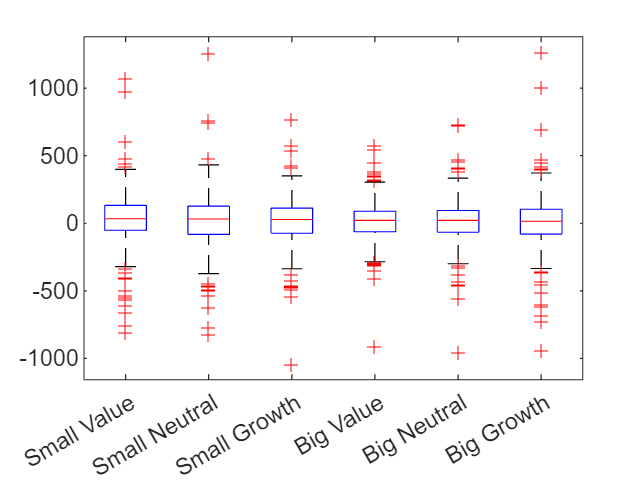

Ports      = constructFF3Ports(FinData,Prices,Returns);
figure
boxplot(100*52*[Ports.smallvaluePortReturns Ports.smallneutralPortReturns Ports.smallgrowthPortReturns Ports.bigvaluePortReturns Ports.bigneutralPortReturns Ports.biggrowthPortReturns],["Small Value"; "Small Neutral"; "Small Growth"; "Big Value"; "Big Neutral"; "Big Growth"])

## Construct Fama French 3 Factors

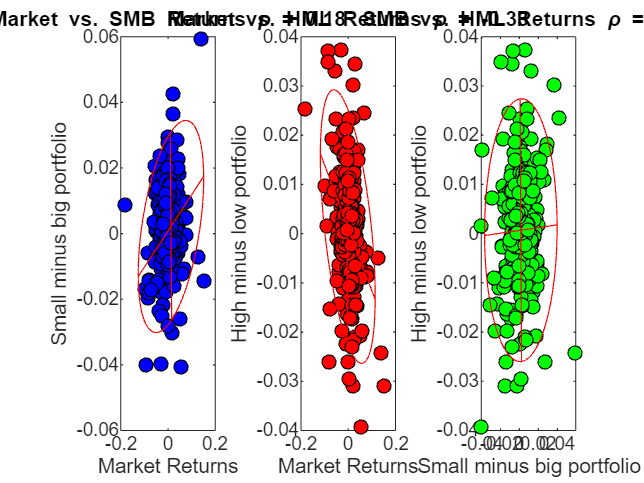

wMarket       = FinData.MarketCap/sum(FinData.MarketCap);
returnsMarket = Returns{:,:}*wMarket;
returnsSMB    = 1/3*(Ports.smallvaluePortReturns + Ports.smallneutralPortReturns + Ports.smallgrowthPortReturns) - 1/3*(Ports.bigvaluePortReturns + Ports.bigneutralPortReturns + Ports.biggrowthPortReturns);
returnsHML    = 1/2*(Ports.smallvaluePortReturns + Ports.bigvaluePortReturns) - 1/2*(Ports.smallgrowthPortReturns + Ports.biggrowthPortReturns);

plot3FactorReturns(returnsMarket,returnsSMB,returnsHML)

## Beta to the 3 Factors

secReturns = E.largeReturns.CA;
secReturnsMinusRf = secReturns-LIBOR.Rates(2:end);
[MdlFF3,MdlCAPM] = fitFF3FactorModel(LIBOR,returnsMarket,returnsSMB,returnsHML,secReturns)

MdlFF3 = Linear regression model:
    RiMinusRf ~ 1 + Rsmb + Rhml + RmMinusRf

Estimated Coefficients:
                    Estimate         SE        tStat        pValue  
                   ___________    ________    ________    __________

    (Intercept)    -0.00065601     0.00169    -0.38817       0.69818
    Rsmb              0.088082     0.14356     0.61355          0.54
    Rhml               0.18881     0.15142      1.2469       0.21344
    RmMinusRf            0.998    0.048396      20.622    1.6041e-58


Number of observations: 290, Error degrees of freedom: 286
Root Mean Squared Error: 0.0279
R-squared: 0.626,  Adjusted R-Squared: 0.622
F-statistic vs. constant model: 160, p-value = 8.94e-61

MdlCAPM = Linear regression model:
    RiMinusRf ~ 1 + RmMinusRf

Estimated Coefficients:
                    Estimate         SE        tStat      pValue  
                   ___________    _________    ______    _________

    (Intercept)    -0.00026221    0.0016595    -0.158      0.87456
    RmMinusRf          0.98766     0.045278    21.813    5.972e-63


Number of observations: 290, Error degrees of freedom: 288
Root Mean Squared Error: 0.0279
R-squared: 0.623,  Adjusted R-Squared: 0.622
F-statistic vs. constant model: 476, p-value = 5.97e-63

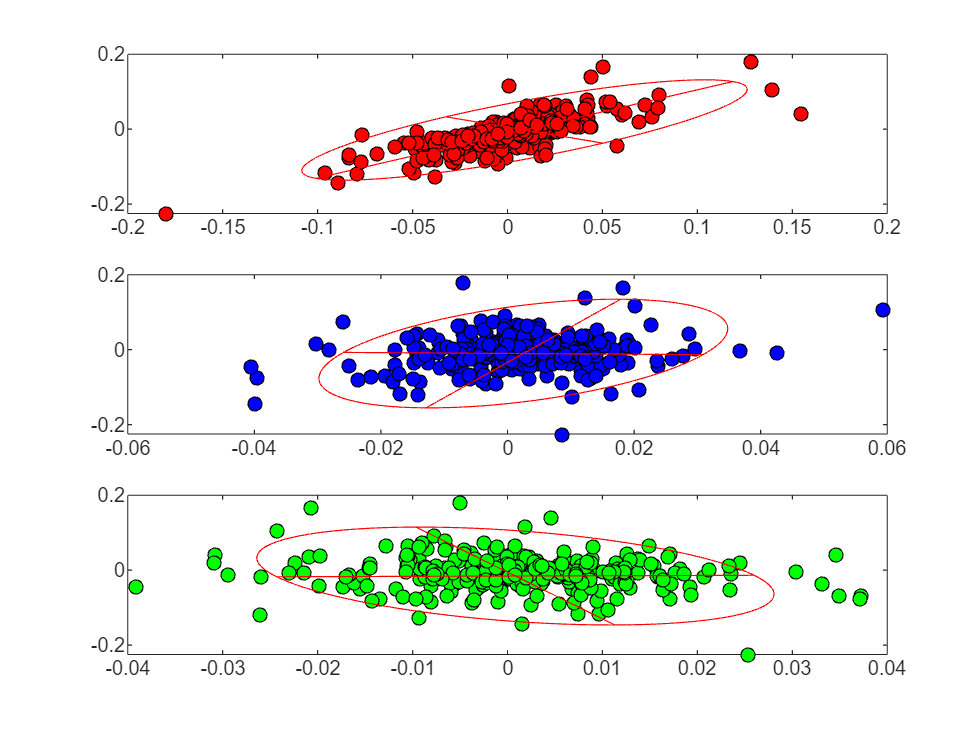

figure
subplot(3,1,1)
plot(returnsMarket,secReturnsMinusRf,'ko','MarkerFaceColor','red')
fit_ellipse(returnsMarket,secReturnsMinusRf,gca);

subplot(3,1,2)
plot(returnsSMB,secReturnsMinusRf,'ko','MarkerFaceColor','blue')
fit_ellipse(returnsSMB,secReturnsMinusRf,gca);
subplot(3,1,3)
plot(returnsHML,secReturnsMinusRf,'ko','MarkerFaceColor','green')
fit_ellipse(returnsHML,secReturnsMinusRf,gca);

## Beta to the 3 Factors over time

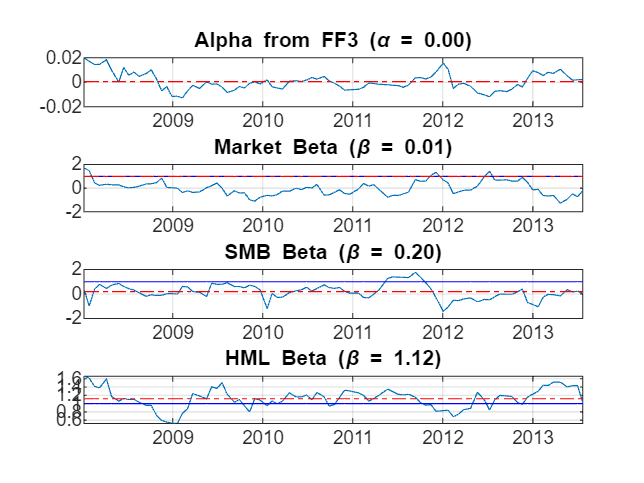

StepSize   = 3;
WindowSize = 20;
fitRolling3FactorModel(secReturns,StepSize,WindowSize,Dates,LIBOR,returnsMarket,returnsSMB,returnsHML);